# **LBYEC3B Project 1 - BAYETA | TAN | TUPAL**

Wine Quality Classification

% Clearvars
clc; clearvars;

% Read data set for wine quality classification train and test
wine_train = readtable('train.csv');
wine_test  = readtable('test.csv');

## Statistical Analysis

% Change wineType from str to idx
% wine_train.wineType = grp2idx(wine_train.wineType);
% wine_test.wineType  = grp2idx(wine_test.wineType);

% Remove ID
test_id             = wine_test.id;
qlty                = wine_train.quality;
wine_train.id       = [];
wine_test.id        = [];
wine_train.wineType = [];
wine_test.wineType  = [];

% Displays the wine features
colnames = wine_train.Properties.VariableNames

colnames = 1×12 cell array
    {'fixedAcidity'}    {'volatileAcidity'}    {'citricAcid'}    {'residualSugar'}    {'chlorides'}    {'freeSulfurDioxide'}    {'totalSulfurDioxide'}    {'density'}    {'pH'}    {'sulphates'}    {'alcohol'}    {'quality'}


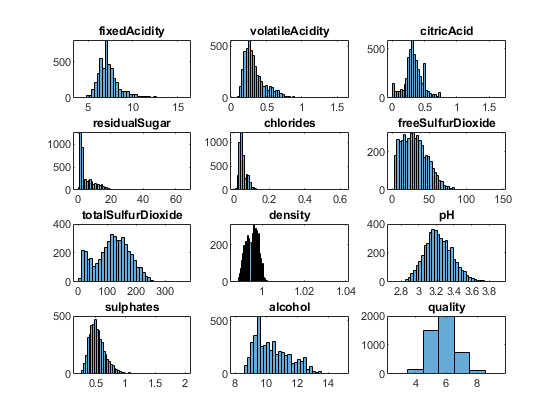

figure('Name','Wine Features', 'NumberTitle', 'off')
for idx = 1: length(colnames)
    col_name = string(colnames(:,idx));
        subplot(4,3,idx)
        histogram(wine_train.(col_name))
        title(col_name)
        % disp(idx)
end

summary(wine_train)

Variables:

    fixedAcidity: 4548×1 double

        Values:

            Min          4.2  
            Median       7.1  
            Max         15.9  

    volatileAcidity: 4548×1 double

        Values:

            Min         0.08  
            Median      0.29  
            Max         1.58  

    citricAcid: 4548×1 double

        Values:

            Min            0  
            Median      0.32  
            Max         1.66  

    residualSugar: 4548×1 double

        Values:

            Min          0.6  
            Median       2.9  
            Max         65.8  

    chlorides: 4548×1 double

        Values:

            Min        0.012  
            Median     0.047  
            Max        0.611  

    freeSulfurDioxide: 4548×1 double

        Values:

            Min            1  
            Median        29  
            Max        146.5  

    totalS

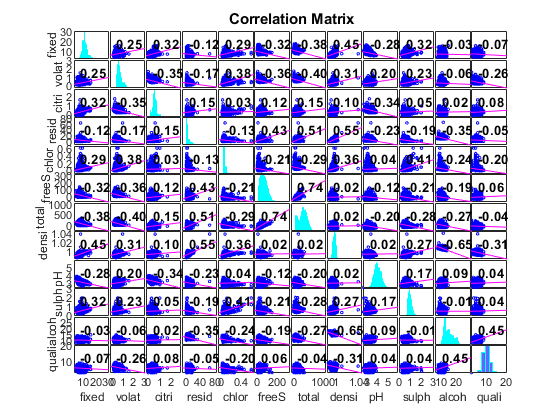

% Generate correlation matrix
figure()
corrplot(wine_train)

% Display colnames
colnames

colnames = 1×12 cell array
    {'fixedAcidity'}    {'volatileAcidity'}    {'citricAcid'}    {'residualSugar'}    {'chlorides'}    {'freeSulfurDioxide'}    {'totalSulfurDioxide'}    {'density'}    {'pH'}    {'sulphates'}    {'alcohol'}    {'quality'}


## Preprocessing

% Feature ranking by chi-squared test
% Univariate feature ranking for classification using chi-square tests
% fscchi2 examines whether each predictor variable is independent of 
% a response variable by using individual chi-square tests.
figure()
[idx2,scores2]    = fscchi2(removevars(wine_train, {'quality'}), qlty)

idx2 =     11     8     5     2     3     6     7    10     4     1     9


scores2 =    15.2587  132.2661  102.3837   18.0911  163.7644   63.7452   57.6814  278.2515    7.7558   23.1303  524.0744


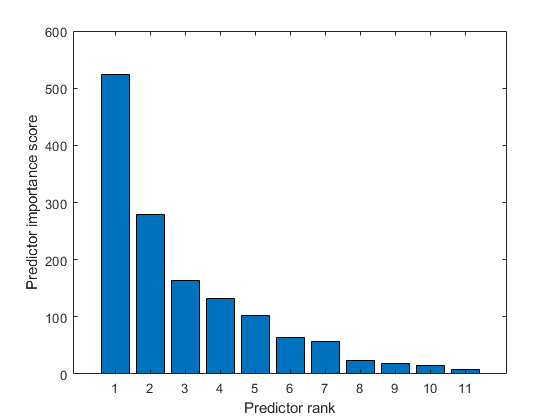

bar(scores2(idx2))
xlabel('Predictor rank')
ylabel('Predictor importance score')

% Tabulate idx2 vs scores2
top_col = idx2';
top_col_scores = scores2';
idx2vsscores2 = table(top_col, top_col_scores);
idx2vsscores2

idx2vsscores2 = 11×2 table
    top_col    top_col_scores
    _______    ______________

      11           15.259    
       8           132.27    
       5           102.38    
       2           18.091    
       3           163.76    
       6           63.745    
       7           57.681    
      10           278.25    
       4           7.7558    
       1            23.13    
       9           524.07    


% Display colnames
colnames

colnames = 1×12 cell array
    {'fixedAcidity'}    {'volatileAcidity'}    {'citricAcid'}    {'residualSugar'}    {'chlorides'}    {'freeSulfurDioxide'}    {'totalSulfurDioxide'}    {'density'}    {'pH'}    {'sulphates'}    {'alcohol'}    {'quality'}


% Drop quality
wine_train.quality = [];
% Functions for outliers (did not work)
% new_data = filloutliers(wine_train, 'spline','percentile', [10 90]);

% Normalize
norm_train = normalize(wine_train);
norm_test  = normalize(wine_test);

% Select ranked features
mask = idx2(1:8)

mask =     11     8     5     2     3     6     7    10


wine_feature = norm_train{:, mask};
wine_target = double(qlty);
wine_testing = norm_test{:, mask};

## Models and Results

Models are trained under the Classification App of MATLAB. It can be replicated by checking the parameters stated in each section below.

% % Bagged Trees (Random-Forest), Default Params
% id = test_id;
% quality = FBGTREE_DEF_669.predictFcn(wine_testing);

Unable to resolve the name FBGTREE_DEF_669.predictFcn.

% disp('Quality Prediction for Final1')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final1_baggedtrees_def_669.csv');

% % Bagged Trees (Random-Forest), 100 learners
% id = test_id;
% quality = FBGTREE_100L_677.predictFcn(wine_testing);
% disp('Quality Prediction for Final2')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final2_baggedtrees_100L_677.csv');

% % Weighted KNN, Default Params
% id = test_id;
% quality = FWKNN_DEF_654.predictFcn(wine_testing);
% disp('Quality Prediction for Final3')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final3_weightedKNN_def_654.csv');

% % Fine Gaussian SVM, Default Params
% id = test_id;
% quality = FFGSVM_DEF_628.predictFcn(wine_testing);
% disp('Quality Prediction for Final4')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final4_finegaussianSVM_def_628.csv');

% % Fine Tree, default parameters
% id = test_id;
% quality = FFTREE_DEF_528.predictFcn(wine_testing);
% disp('Quality Prediction for Final5')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final5_finetree_def_528.csv');

% % Cubic KNN, default
% id = test_id;
% quality = FCKNN_DEF_545.predictFcn(wine_testing);
% disp('Quality Prediction for Final6')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final6_cubicKNN_def_545.csv'); % 7 in window

% % RUS Boosted Trees, default parameters
% id = test_id;
% quality = FRUSBST_DEF_327.predictFcn(wine_testing);
% disp('Quality Prediction for Final7')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final7_RUSBoostedTrees_def_327.csv');

% % Boosted Trees, default
% id = test_id;
% quality = FBSTREE_DEF_532.predictFcn(wine_testing);
% disp('Quality Prediction for Final8')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final8_BoostedTrees_def_532.csv');

% % Weighted KNN, k = 68
% id = test_id;
% quality = FWKNN_68K_680.predictFcn(wine_testing);
% disp('Quality Prediction for Final9')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final9_WKNN_68k_680.csv');

% % Trilayered NN, default
% id = test_id;
% quality = WTRINN_DEF_541.predictFcn(wine_testing);
% disp('Quality Prediction for Final10')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final10_TRINN_541.csv');

% % Medium NN, default
% id = test_id;
% quality = FMEDNN_DEF_553.predictFcn(wine_testing);
% disp('Quality Prediction for Final11')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final11_MEDNN_553.csv');

% % Coarse Gaussian SVM
% id = test_id;
% quality = FCGSVM_DEF_524.predictFcn(wine_testing);
% disp('Quality Prediction for Final12')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final12_CoarseGaussSVM_524.csv');

% % Bagged Trees (Random Forest), 250 learners
% id = test_id;
% quality = FBGTREE_250L_679.predictFcn(wine_testing);
% disp('Quality Prediction for Final13')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final13_baggedtrees_250L_679.csv');

% % Coarse KNN, default
% id = test_id;
% quality = FCKNN_DEF_533.predictFcn(wine_testing);
% disp('Quality Prediction for Final14')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final14_coarseKNN_def_533.csv');
% 

% % Bagged Trees (Random Forest), 68 learners
% id = test_id;
% quality = FBGTREE_68L_673.predictFcn(wine_testing);
% disp('Quality Prediction for Final15')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final15_baggedtrees_68L_673.csv');

% % Bagged Trees (Random Forest), 500 learners
% disp('nag run ako')
% id = test_id;
% quality = FBGTREE_500L_683.predictFcn(wine_testing);
% disp('Quality Prediction for Final16')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final16_baggedtrees_500L_683.csv');

% % Bagged Trees (Random Forest), 1000 learners
% id = test_id;
% quality = FBGTREE_1000L_680.predictFcn(wine_testing);
% disp('Quality Prediction for Final17')
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'final17_baggedtrees_1000L_680.csv');

% id = test_id;
% quality = BAGTREE5K66.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'lastsubmission3.csv');

% id = test_id;
% quality = BAGTREE5k668.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'lastsubmission4.csv');

% id = test_id;
% quality = WKK5k65.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'lastsubmission5.csv');

% id = test_id;
% quality = DEFBGTREE68.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'lastsubmission6.csv');

% id = test_id;
% quality = DEFWKNN669.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% writetable(exported , 'lastsubmission7.csv');

% id = test_id;
% quality = BAGTREESIDX1_67.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx1 (11 param)
% writetable(exported , 'lastsubmission8.csv');

% id = test_id;
% quality = bg66idx8.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param)
% writetable(exported , 'lastsubmission9.csv');

% id = test_id;
% quality = bg671.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission10.csv');

% id = test_id;
% quality = bgg655id2x17.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission11.csv');

% id = test_id;
% quality = BAGTREEUPDATED677IDX28.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission12.csv');

% id = test_id;
% quality = bg673idx19.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission13.csv');

% id = test_id;
% quality = bg658idx18.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission14.csv');

% id = test_id;
% quality = bg67idx18.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission15.csv');

% id = test_id;
% quality = trainedModelbg100677idx28.predictFcn(wine_testing);
% tabulate(quality)
% exported = table(id, quality);
% %idx2 (9 param 1-9)
% writetable(exported , 'lastsubmission16.csv');